# **Matlab案例代码解析**

## 1. 基础函数使用案例

### 1.1  基础知识技巧

#### 1.1.5 Axis铺满整个figure

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

如果是在实时脚本里输出的图像，直接导出成图片即可，或者复制输出后粘贴，也能达到类似的效果

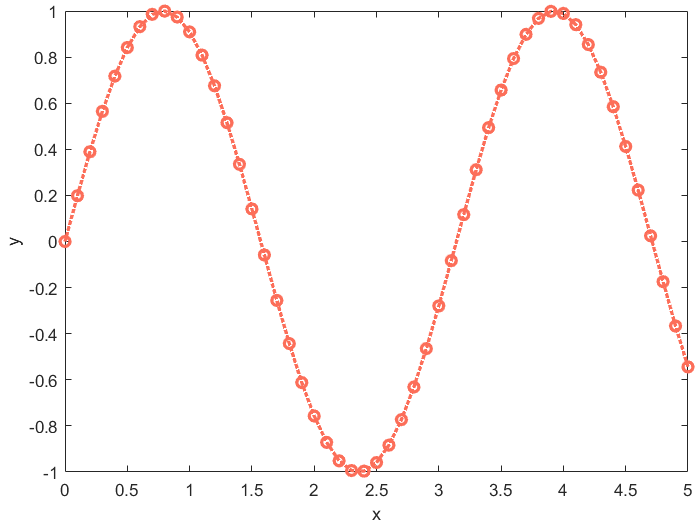

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
x = 0 : 0.1 : 5;
y1 = sin(2*x);
y2 = cos(3*x);
figure
plot(x, y1, 'o:', 'LineWidth', 2, 'Color', all_colors(1, :));
xlabel('x');
ylabel('y');
set(gca, 'looseInset', [0 0 0 0]);

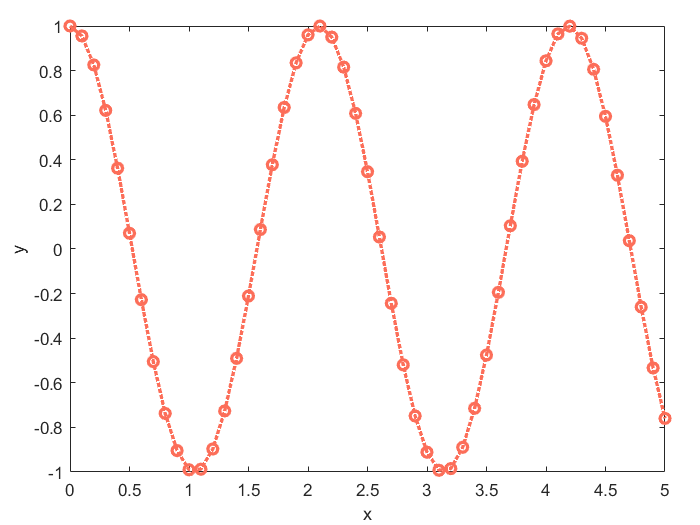

figure
plot(x, y2, 'o:', 'LineWidth', 2, 'Color', all_colors(1, :))
xlabel('x');
ylabel('y');
set(gca, 'Position', [0.1 0.1 0.85 0.85]);